## MATLABからSimulinkを実行する

パラメーター

freq = 1;

モデルを実行

simulation_data = sim("calculate_wave.slx");

実行結果を確認

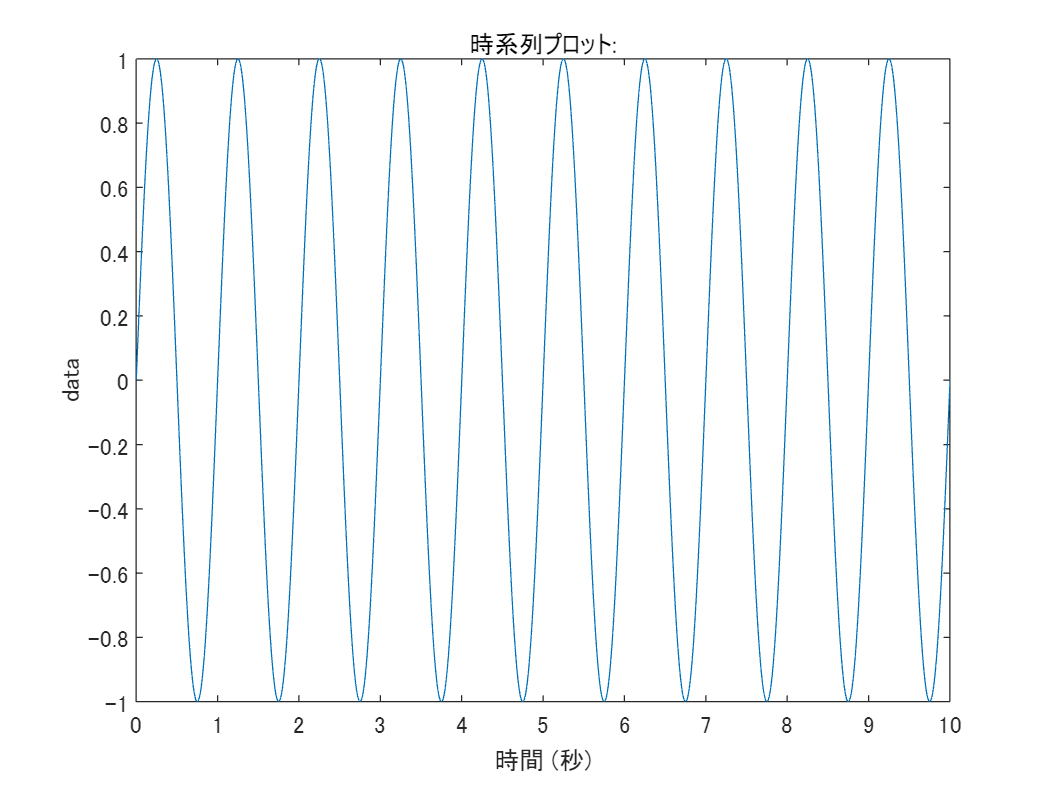

plot(simulation_data.yout{1}.Values);

## パラメーターを変えながら繰り返し実行

simulation_data = cell(3, 1);

for i = 1:numel(simulation_data)
    freq = i;
    simulation_data{i} = sim("calculate_wave.slx");
end

結果を確認

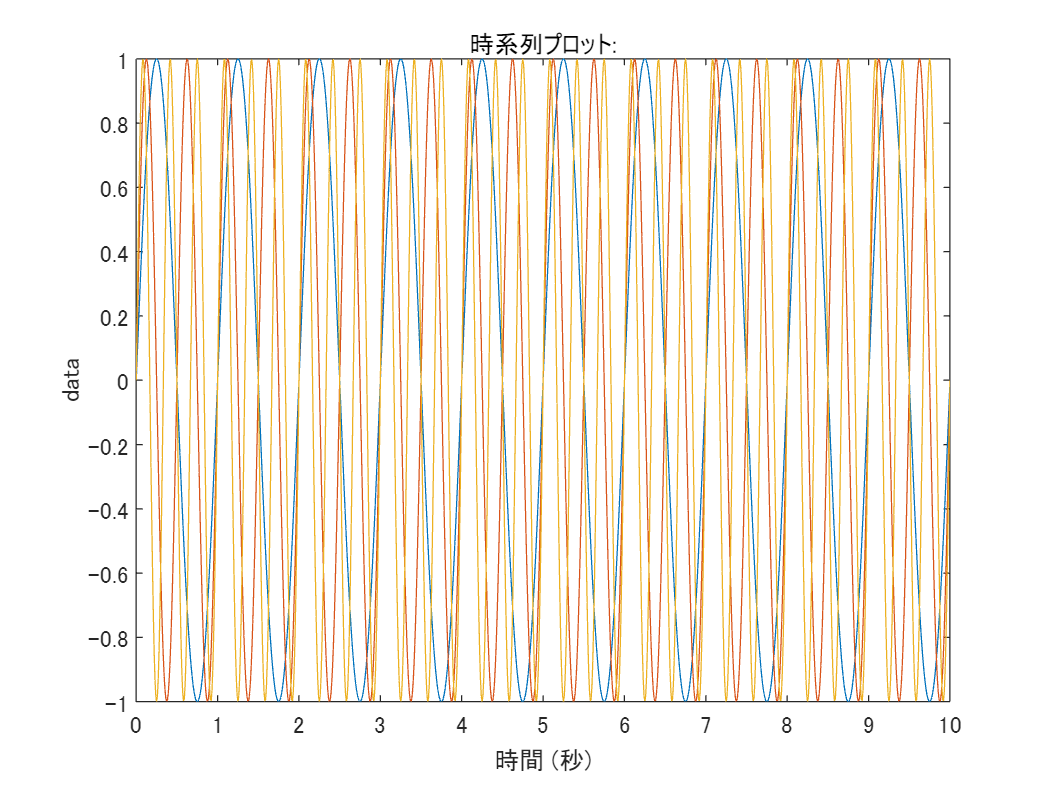

plot(simulation_data{1}.yout{1}.Values);
hold on;
plot(simulation_data{2}.yout{1}.Values);
plot(simulation_data{3}.yout{1}.Values);
hold off